## Ali Saeizadeh - 810196477

## Section 1

### 1.

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab6'
clear all; clc; close all;
dcl_init;
k = 2;
M = 2^k;
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k)

b_tx =      0     0
     1     1
     0     0
     0     0
     0     1
     0     1
     0     1
     0     0
     0     0
     1     0


### 2.

if(modulation == 'fsk')
    flg_gray_encode = 0
end

flg_gray_encode = 0

if(flg_gray_encode == 1)
    b_code = gray_code(k)    
else
    b_code = non_code(k) 
end 

b_code =      0     0
     0     1
     1     0
     1     1



sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
sym_idx

sym_idx =      1
     4
     1
     1
     2
     2
     2
     1
     1
     3


### 3

[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_gen_mode);

tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
rx_smpl = tx_smpl_delayed .* exp(1i*chnl_phase_offset);

Eb =  1/log2(M) 

Eb = 0.5000

EbNo = db2pow(snr_max)

EbNo = 10

var_noise = (Eb ./ EbNo)

var_noise = 0.0500

mean_noise = 0

mean_noise = 0

noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise

noise_smpl =    0.0869 - 0.2539i
   0.2025 + 0.1060i
   0.0870 - 0.0580i
   0.0918 + 0.0734i
   0.1214 + 0.0699i
   0.0129 - 0.0083i
  -0.0629 - 0.0404i
   0.0052 - 0.1901i
  -0.1422 + 0.0841i
  -0.0103 + 0.1834i


rx_smpl_noise = rx_smpl + noise_smpl

rx_smpl_noise =    0.2119 - 0.2539i
   0.3275 + 0.1060i
   0.2120 - 0.0580i
   0.2168 + 0.0734i
   0.2464 + 0.0699i
   0.1379 - 0.0083i
   0.0621 - 0.0404i
   0.1302 - 0.1901i
  -0.0172 + 0.0841i
   0.1147 + 0.1834i


modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode

modulation = 'fsk'

M = 4

fs = 10000000

smpl_per_symbl = 64

pulse_name = 'rectangular'

rx_mode = 'matched_filter'

[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);

det_bit = b_code(det_sym_idx,:)

det_bit =      0     0
     1     1
     0     0
     0     0
     0     1
     0     1
     0     1
     0     0
     0     0
     1     0


ser = sum(det_sym_idx ~= sym_idx)/length(sym_idx)

ser = 1.0000e-05

ber = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2))

ber = 5.0000e-06

serFSK = zeros(size(snr_db));
berFSK = zeros(size(snr_db));
for i = 0:1:10
    Eb =  1/log2(M);
    EbNo = db2pow(i);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    rx_smpl_eq = rx_smpl_noise;
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    det_bit = b_code(det_sym_idx,:);
    serFSK(i + 1) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
    berFSK(i + 1) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end


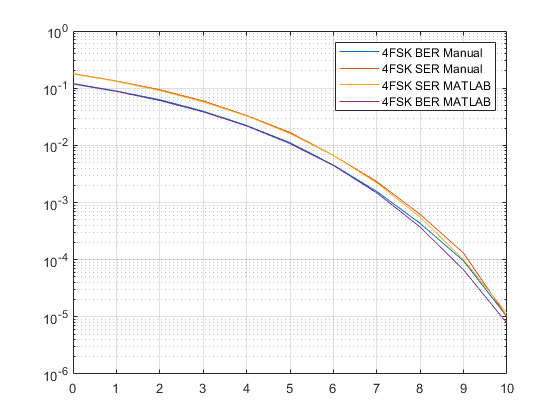

figure
[berFSK_matlab, serFSK_matlab] = berawgn(snr_db,modulation,M,'coherence');
semilogy(snr_db,berFSK)
hold on
semilogy(snr_db,serFSK)
hold on
semilogy(snr_db,serFSK_matlab)
hold on
semilogy(snr_db,berFSK_matlab)
legend('4FSK BER Manual','4FSK SER Manual', '4FSK SER MATLAB', '4FSK BER MATLAB')
grid on

figure

As we can see in BER plots we get same behaviour from both MATLAB Coherent FSK and our manual implementation.